clear all
clc
pause(1);


p = 0

p = 0

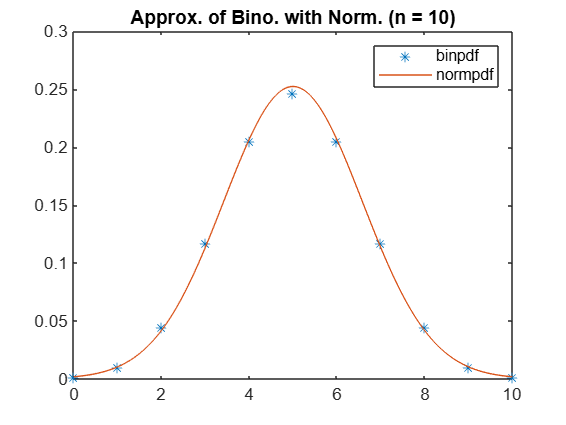

while p < 0.05 | p > 0.95
    p=input("prob of succes (0.05 <= p <= 0.95)=");
end


for n = 1:10
    k=0:n;
    px=binopdf(k, n, p);
    plot(k, px, '*');
    hold on;

    mu = n * p;
    sigma = sqrt(n * p * (1 - p));
    kreal = 0:0.01:n;
    normpx = normpdf(kreal, mu, sigma);
    plot(kreal, normpx);
    hold off;

    legend("binpdf", "normpdf");
    title("Approx. of Bino. with Norm. (n = "+n+")");

    pause(0.5);
end